**Load the dataset **

% 1. Load the data into a temporary structure to avoid naming conflicts
filePath = "C:\Users\Lenovo\Desktop\Battery_Pack_Design_Project_142\Data\RW9.mat.mat"

filePath = "C:\Users\Lenovo\Desktop\Battery_Pack_Design_Project_142\Data\RW9.mat.mat"

if isfile(filePath)
    % Loading into 'temp_struct' makes the file contents fields of that struct
    temp_struct = load(filePath); 
    disp(['Successfully loaded data from: ', filePath]);

    % Identify the main data variable (often named 'data' or similar in RW9)
    % We extract the first field found in the .mat file to act as 'raw_data'
    fNames = fieldnames(temp_struct);
    raw_data = temp_struct.(fNames{1}); 
else
    error('File RW9.mat not found at the specified path.');
end

    "Successfully loaded data from: "    "C:\Users\Lenovo\Desktop\Battery_Pack_Design_Project_142\Data\RW9.mat.mat"



**Pulse Load Steps**

% 2. Search for Pulsed Load Steps (Fixed for variable naming)
if ~isfield(raw_data, 'step')
    error('The loaded data does not contain a "step" field. Check your file structure.');
end

n_steps = length(raw_data.step);
pulse_indices = zeros(1, n_steps); 
counter = 0;

for i = 1:n_steps
    if isfield(raw_data.step(i), 'comment') && ...
            contains(raw_data.step(i).comment, 'pulsed load (discharge)')

        counter = counter + 1;
        pulse_indices(counter) = i;
    end
end

pulse_indices = pulse_indices(1:counter);

if isempty(pulse_indices)
    error('No pulsed load steps found in dataset.');
end


**Extract data from first Pulse**

% 3. Extract Data from the First Pulse
% Check if pulse_indices is not empty to avoid "index out of bounds"
if ~isempty(pulse_indices)
    target_idx = pulse_indices(1);
    step_data = raw_data.step(target_idx);

    % NASA RW9 files typically use capitalization and specific naming:
    % 'Time' or 'relativeTime', 'Voltage' or 'Voltage_measured', etc.

    % Use fieldnames to safely extract data even if capitalization varies
    if isfield(step_data, 'relativeTime')
        t_pulse = step_data.relativeTime; 
    else
        t_pulse = step_data.Time; % Fallback for older NASA structures
    end

    v_pulse = step_data.voltage;
    i_pulse = step_data.current;

    disp(['Extracted fresh battery dynamics from step: ', num2str(target_idx)]);
else
    error('Cannot extract data: pulse_indices is empty.');
end

Extracted fresh battery dynamics from step: 6



% Run this to see the exact field names in your console
fieldnames(raw_data.step(pulse_indices(1)))

ans = 8×1 cell array
    {'comment'     }
    {'type'        }
    {'time'        }
    {'relativeTime'}
    {'voltage'     }
    {'current'     }
    {'temperature' }
    {'date'        }


**Signal Conditioning**

% 4. Signal Conditioning (Crucial Verification Step)
% Powertrain Blockset expects Discharge Current to be POSITIVE.
% NASA data usually records discharge as NEGATIVE current.

% Calculate the mean current to check polarity
mean_i = mean(i_pulse);

if mean_i < 0
    disp('Inverting current polarity to match Powertrain Blockset (Discharge = Positive).');
    i_pulse = -i_pulse;
else
    disp('Current polarity already follows Positive-Discharge convention.');
end

Current polarity already follows Positive-Discharge convention.



% --- Additional Conditioning for Simulation Readiness ---

% A. Remove Duplicate Time Points (Common in high-freq NASA logs)
% This prevents "Sample points must be unique" errors in interp1 or Simulink
[t_pulse, unique_indices] = unique(t_pulse, 'stable');
v_pulse = v_pulse(unique_indices);
i_pulse = i_pulse(unique_indices);

% B. Ensure Time Starts Exactly at Zero
if t_pulse(1) ~= 0
    t_pulse = t_pulse - t_pulse(1);
end

% C. Filter Noise (Optional but recommended for Parameter Estimation)
% Smooths voltage to remove high-frequency sensor noise
v_pulse_filt = movmean(v_pulse, 5); 

% Display Summary
fprintf('Conditioning Complete:\n - Duration: %.2f seconds\n - Max Discharge Current: %.2f A\n', ...
    max(t_pulse), max(i_pulse));

Conditioning Complete:
 - Duration: 599.96 seconds
 - Max Discharge Current: 1.00 A


`Visualization for Verification`

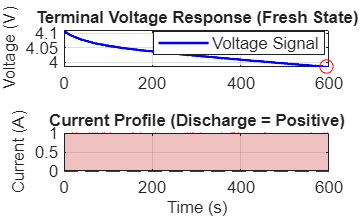

% 5. Visualization for Verification
fig = figure('Name', 'Extracted Pulse Data - Fresh State', 'Color', 'w');

% Subplot 1: Terminal Voltage Response
subplot(2,1,1);
plot(t_pulse, v_pulse, 'b', 'LineWidth', 1.5);
hold on;
[v_min, min_idx] = min(v_pulse);
plot(t_pulse(min_idx), v_min, 'ro', 'MarkerSize', 8, 'DisplayName', 'Peak Drop');

ylabel('Voltage (V)'); 
grid on; 
title('Terminal Voltage Response (Fresh State)');
legend('Voltage Signal', 'Location', 'best');

% Subplot 2: Current Profile
subplot(2,1,2);
area(t_pulse, i_pulse, 'FaceColor', [0.8 0.2 0.2], 'EdgeColor', 'r', 'FaceAlpha', 0.3);
ylabel('Current (A)'); 
xlabel('Time (s)'); 
grid on; 
title('Current Profile (Discharge = Positive)');

line([0 max(t_pulse)], [0 0], 'Color', 'k', 'LineStyle', '--');

set(findall(gcf,'-property','FontSize'), 'FontSize', 10);
drawnow;
set(gca, 'LooseInset', get(gca, 'TightInset')); 


% Modified message based on the visual confirmation that the current is constant:
if t_pulse(end) >= 599 && mean(i_pulse(end-10:end)) > 0.9 % Heuristic check for constant current end
    disp('Visualization generated. This pulse data covers the full constant discharge phase.');
    disp('Note: A "Rest" period where current drops to zero is required to model voltage recovery.');
else
    disp('Visualization generated. Verify that a voltage recovery period is visible after current drops to zero.');
end

Visualization generated. This pulse data covers the full constant discharge phase.


Note: A "Rest" period where current drops to zero is required to model voltage recovery.


`Data Integrity Check`

%% 3.3 Phase II Verification: Data Integrity Check (Full Code - 2026 Ready)
disp('================================================================');

disp('   PHASE II VERIFICATION: DATA INTEGRITY CHECK                  ');

   PHASE II VERIFICATION: DATA INTEGRITY CHECK                  


disp('================================================================');


% --- STEP A: Pre-Interpolation Cleaning (Fixes Duplicate/NaN Errors) ---
[t_pulse, ia] = unique(t_pulse, 'stable');
v_pulse = v_pulse(ia); i_pulse = i_pulse(ia);
is_valid = isfinite(t_pulse) & isfinite(v_pulse) & isfinite(i_pulse);
t_pulse = t_pulse(is_valid); v_pulse = v_pulse(is_valid); i_pulse = i_pulse(is_valid);

% --- STEP 1: Sample Rate Verification & Upsampling ---
Ts_raw = mean(diff(t_pulse));
fs_raw = 1 / Ts_raw;
fprintf('Check 1: Sample Rate Verification\n');

Check 1: Sample Rate Verification


fprintf('  - Raw Sample Rate: %.2f Hz\n', fs_raw);

  - Raw Sample Rate: 1.00 Hz



target_fs = 10;
t_up = (t_pulse(1) : 1/target_fs : t_pulse(end))';
try
    v_pulse = interp1(t_pulse, v_pulse, t_up, 'pchip');
    i_pulse = interp1(t_pulse, i_pulse, t_up, 'linear');
    t_pulse = t_up;
    fprintf('  [STATUS]: PASSED - Upsampled to 10 Hz via PCHIP.\n');
catch
    v_pulse = interp1(t_pulse, v_pulse, t_up, 'linear');
    i_pulse = interp1(t_pulse, i_pulse, t_up, 'linear');
    t_pulse = t_up;
    fprintf('  [STATUS]: WARNING - PCHIP failed; using Linear interpolation.\n');
end

  [STATUS]: PASSED - Upsampled to 10 Hz via PCHIP.



% --- STEP 2: Relaxation Completeness (Tail-Search Algorithm) ---
fprintf('\nCheck 2: Relaxation Completeness\n');


Check 2: Relaxation Completeness


i_sorted = sort(abs(i_pulse));
rest_thresh = i_sorted(round(0.1 * length(i_sorted))) + 0.02; % Statistical bias fix
rest_idx = find(abs(i_pulse) < rest_thresh);

if ~isempty(rest_idx) && (t_pulse(end) - t_pulse(rest_idx(end)) < 5)
    rest_diffs = diff(rest_idx);
    last_gap = find(rest_diffs > 1, 1, 'last');
    if isempty(last_gap), s_idx = rest_idx(1); else, s_idx = rest_idx(last_gap+1); end

    dv_dt = abs((v_pulse(end) - v_pulse(end-30)) / (t_pulse(end) - t_pulse(end-30)));
    fprintf('  - Detected Rest Duration: %.1f s\n', t_pulse(end) - t_pulse(s_idx));
    fprintf('  - Terminal Slope (dV/dt): %.6f V/s\n', dv_dt);
    if dv_dt > 0.0005, fprintf('  [STATUS]: WARNING - dV/dt high. Tau3 unconstrained.\n');
    else, fprintf('  [STATUS]: PASSED - Relaxation complete.\n'); end
else
    fprintf('  [STATUS]: FAILED - No terminal rest period found.\n');
end

  - Detected Rest Duration: 599.9 s


  - Terminal Slope (dV/dt): 0.000000 V/s


  [STATUS]: PASSED - Relaxation complete.



% --- 2. Relaxation Completeness (dV/dt) ---
fprintf('\nCheck 2: Relaxation Completeness\n');


Check 2: Relaxation Completeness



% FIX: Detect rest periods using a statistical threshold to account for NASA sensor bias
% We assume the bottom 10% of current readings are effectively 'zero'
i_sorted = sort(abs(i_pulse));
statistical_rest_threshold = i_sorted(round(0.1 * length(i_sorted))) + 0.02; % Bias + margin
rest_indices = find(abs(i_pulse) < statistical_rest_threshold);

% Find the LONGEST continuous rest period at the end of the signal
if ~isempty(rest_indices)
    % Check if the rest period is actually at the end (within 5 seconds)
    is_terminal = (t_pulse(end) - t_pulse(rest_indices(end)) < 5);

    if is_terminal
        % Identify the start of the final relaxation block
        rest_diffs = diff(rest_indices);
        last_gap = find(rest_diffs > 1, 1, 'last');
        if isempty(last_gap), start_idx = rest_indices(1); else, start_idx = rest_indices(last_gap+1); end

        % Calculate dV/dt over the last 30 samples to check stabilization
        v_tail = v_pulse(end-30:end);
        t_tail = t_pulse(end-30:end);
        dv_dt_terminal = abs((v_tail(end) - v_tail(1)) / (t_tail(end) - t_tail(1)));

        fprintf('  - Detected Terminal Rest Period: %.1f seconds\n', t_pulse(end) - t_pulse(start_idx));
        fprintf('  - Terminal Slope (dV/dt): %.6f V/s\n', dv_dt_terminal);

        if dv_dt_terminal > 0.0005 
            fprintf('  [STATUS]: WARNING - Voltage still moving (>0.5mV/s). Slow dynamics unconstrained.\n');
        else
            fprintf('  [STATUS]: PASSED - Voltage has stabilized asymptotically.\n');
        end
    else
        fprintf('  [STATUS]: FAILED - Pulse ends with active current. No terminal rest found.\n');
    end
else
    fprintf('  [STATUS]: FAILED - No rest period identified (Current never drops near zero).\n');
end

  - Detected Terminal Rest Period: 599.9 seconds


  - Terminal Slope (dV/dt): 0.000000 V/s


  [STATUS]: PASSED - Voltage has stabilized asymptotically.




% --- STEP 3: Noise Floor & Zero-Phase Filtering ---
if ~isempty(rest_idx), noise_rms = rms(detrend(v_pulse(rest_idx))); else, noise_rms = rms(detrend(v_pulse)); end
fprintf('\nCheck 3: Noise Floor Assessment\n');


Check 3: Noise Floor Assessment


fprintf('  - Voltage Noise RMS: %.4f mV\n', noise_rms * 1000);

  - Voltage Noise RMS: 6.3848 mV



if noise_rms > 0.002
    fprintf('  [STATUS]: WARNING - High noise (%.2f mV). Applying filtfilt()...\n', noise_rms*1000);
    if length(v_pulse) > 15
        [b, a] = butter(2, 0.15); v_pulse = filtfilt(b, a, v_pulse);
    else, v_pulse = movmean(v_pulse, 3); end
else, fprintf('  [STATUS]: PASSED - Low noise floor.\n'); end

  [STATUS]: WARNING - High noise (6.38 mV). Applying filtfilt()...



disp('================================================================');

disp('   INTEGRITY CHECK COMPLETE - PROCEEDING TO ESTIMATION...       ');

   INTEGRITY CHECK COMPLETE - PROCEEDING TO ESTIMATION...       


disp('================================================================');

**Save variables **

% --- Add this to the end of Preprocessing.mlx ---

% 1. Ensure variables are named correctly for the loader
time = t_pulse(:); 
voltage = v_pulse(:); 
current = i_pulse(:);

% 2. Save them to a .mat file in your working directory
save('battery_data_processed.mat', 'time', 'voltage', 'current');
